## **PL04 Variáveis Aleatórias Multidimensionais**

**Ex1. Duas variáveis aleatórias**

    a) Calcular funções massa de probabilidade marginais de X e Y e representar gráficamente

pxy = [0.3 0.2 0.0; 0.1 0.15 0.05; 0.0 0.1 0.1]

pxy =     0.3000    0.2000         0
    0.1000    0.1500    0.0500
         0    0.1000    0.1000


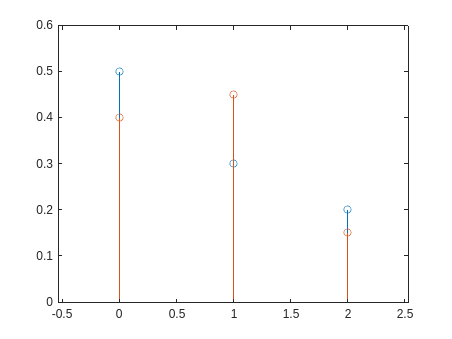

px = sum(pxy,2);
py = sum(pxy,1);
x = [0 1 2];
y = x;

stem(x,px);
hold on;
stem(x,py);
hold off;
ylim([0 0.6]);

    b) Calcular média (valor esperado) e a variância de X e Y.

Ex = sum(x.*px');
Ey = sum(y.*py);
disp(['Valor esperado de X: ', num2str(Ex)]);

Valor esperado de X: 0.7


disp(['Valor esperado de Y: ', num2str(Ey)]);

Valor esperado de Y: 0.75


Var(X) = E[X^2] - E[X]

var_x = sum(x.^2.*px') - Ex^2;

var_y = sum(y.^2.*py) - Ey^2;

disp(['Variância de X: ', num2str(var_x)]);

Variância de X: 0.61


disp(['Variância de Y: ', num2str(var_y)]);

Variância de Y: 0.4875


    c) Calcular a correlação, covariância e coeficiente de correlação entre X e Y

% corr(x,y) = E[xy]         % correlação calculada à mão
% = 0 + 1*1*0.15 + 1*2*0.05     + 2*1*0.1 + 2*2*0.1 = 0.15 + 0.1 + 0.2 + 0.4 = 0.85

xx = repmat(x',1,3)

xx =      0     0     0
     1     1     1
     2     2     2


yy = repmat(y,3,1)

yy =      0     1     2
     0     1     2
     0     1     2


corr_xy = sum(sum(xx.*yy.*pxy));

**Covariância(X,Y):**

                                Cov(X,Y) = E[XY] - E[X]*E[Y]

cov_xy = corr_xy - Ex*Ey;

𝜌 **- coeficiente de correlação:**

coefCorr_xy = cov_xy / (sqrt(var_x)*sqrt(var_y));

disp(['Correlação: ', num2str(corr_xy)]);

Correlação: 0.85


disp(['Covariância: ', num2str(cov_xy)]);

Covariância: 0.325


disp(['Coeficiente de correlação: ', num2str(coefCorr_xy)]);

Coeficiente de correlação: 0.59598


Para provar que duas variáveis não são independentes basta que (para todos os elementos, isto se verifique...)

pxy = [0.3 0.2 0.0; 0.1 0.15 0.05; 0.0 0.1 0.1];
px = sum(pxy,2);
py = sum(pxy,1);

px*py;
% basta que para X = 0, Y = 0, P(X=0)*P(Y=0) != pxy(0,0)        // ou qlqr outro elemento
% descomentar pxy e px*py para ver que neste caso são diferentes

**Ex2. Probabilidade conjunta de duas variáveis X e Y**

    a) As variáveis X e Y são independentes?

pxy = [1/8 1/8 1/24; 1/8 1/4 1/8; 1/24 1/8 1/24]
px = sum(pxy,2);
py = sum(pxy,1);

pxpy = px .* py

if ~isequal(pxpy, pxy)
    disp('As variáveis não são independentes');
else
    disp('As variáveis são independentes');
end

**Ex3. Duas variáveis aleatórias (N1 e N2) relativas às classificações de uma turma de 120 alunos em duas UC's (MPEI e POO).**

    a) Gere N1 e N2 para que, antes do arredondamento para o valor inteiro mais próximo, tenham uma distribuição Normal com as seguintes médias e variâncias:

    - média de N1 igual a 14

    - média de N2 igual a 20% superior a N1

    - variâncias iguais a 1/4 da média

% desvio = 1/4 de valorEsperado correspodente = sqrt(var)
valorEsperadoN1 = 14;
desvioN1 = sqrt(1/4 * valorEsperadoN1);
valorEsperadoN2 = valorEsperadoN1 + 0.2*valorEsperadoN1;
desvioN2 = sqrt(1/4 * valorEsperadoN2);
n = 120;
N1 = round(desvioN1.*randn(1,n) + valorEsperadoN1);
N2 = round(desvioN2.*randn(1,n) + valorEsperadoN2);
N1 = max(min(N1, 20), 0);
N2 = max(min(N2, 20), 0);

    b) Obter e representar gráficamente a função probabilidade de massa conjunta de N1 e N2

x = unique(N1);
y = unique(N2);
pN1N2 = zeros(length(x),length(y));

for k = 1:length(N1)
    i = find(x == N1(k));
    j = find(y == N2(k));
    pN1N2(i, j) = pN1N2(i, j) + 1;
end

pN1N2 = pN1N2 / n;

[X, Y] = meshgrid(x,y);
stem3(X,Y,pN1N2','filled');
xlabel('N1');
ylabel('N2');
zlabel('Probabilidade');
title('Função de Massa de Probabilidade Conjunta de N1 e N2');

    c) Coeficiente de correlação de N1 e N2

% Exy = 0;
% for i = 1:length(x)
%     for j = 1:length(y)
%         Exy = Exy + (x(i)*y(j)*pN1N2(i,j));
%     end
% end
% Exy       % E[XY] por iteração

xx = repmat(x',1,length(y));
yy = repmat(y,length(x),1);
E_N1N2 = sum(sum(xx.*yy.*pN1N2));     %% do método que o professor ensinou na aula

% nota: N1 = X      N2 = Y
% Cov(X,Y) = E[XY] - E[X]*E[Y]
pN1 = sum(pN1N2,2);
pN2 = sum(pN1N2,1);
E_N1 = sum(x.*pN1')
E_N2 = sum(y.*pN2)

covN1N2 = E_N1N2 - E_N1*E_N2;   %%

varN1 = sum(x.^2.*pN1') - E_N1^2;
varN2 = sum(y.^2.*pN2) - E_N2^2;
coefCorrN1N2 = covN1N2 / (sqrt(varN1)*sqrt(varN2));     %%

disp(['E[N1N2]: ',num2str(E_N1N2)]);
disp(['Covariância de N1 e N2: ',num2str(covN1N2)]);
disp(['Coeficiente de correlação de N1 e N2: ',num2str(coefCorrN1N2)]);     %% pretendido

    d) N1 e N2 são independentes?

pN1N2
pN1pN2 = pN1 .* pN2

if ~isequal(pN1pN2, pN1N2)
    disp('As variáveis não são independentes');
else
    disp('As variáveis são independentes');
end

**Ex4. Numa cidade:                    ****probabilidade de fazer sol = 0.75**            **probabilidade de chover = 0.25**

**As previsões de meteorologia acertam     ****100% das vezes se o tempo for de chuva**

                                                                       **1/3 das vezes se for um dia de sol**

**Um aluno observa que em ****média o meteorologista tem uma taxa de 50%****. Sabendo que ao prever sempre sol tem uma taxa de acerto de 75% candidata-se ao lugar mas é rejeitado por um responsável que percebe um pouco de probabilidades. Porquê?**

    sugestão: Começar por criar uma tabela com a função massa de probabilidade conjunta.

nota:    P(S ∩ p(S)) = P(S) * P(p(S) | S) = P(p(S)) * P(S | p(S)) 

probSol = 0.75;
probChuva = 0.25;

% meteorologista (1)
probPrevSol_sol1 = 1/3;                             % P(probPrevSol | probSol)
probPrevChuva_chuva1 = 1;                           % P(probPrevChuva | probChuva)
probPrevChuva_sol1 = 1 - probPrevSol_sol1;          % P(probPrevChuva | probSol)
probPrevSol_chuva1 = 1 - probPrevChuva_chuva1;      % P(probPrevSol | probChuva)

% aluno (2)
probPrevSol_sol2 = 1;
probPrevChuva_chuva2 = 0;
probPrevChuva_sol2 = 1 - probPrevSol_sol2;
probPrevSol_chuva2 = 1 - probPrevChuva_chuva2;

% P(probPrevSol ∩ probSol)      - p1
% P(probPrevChuva ∩ probChuva)  - p2
% P(probPrevChuva ∩ probSol)    - p3
% P(probPrevSol ∩ probChuva)    - p4

p1_m = probPrevSol_sol1 * probSol;
p2_m = probPrevChuva_chuva1 * probChuva;
p3_m = probPrevChuva_sol1 * probSol;
p4_m = probPrevSol_chuva1 * probChuva;

p1_a = probPrevSol_sol2 * probSol;
p2_a = probPrevChuva_chuva2 * probChuva;
p3_a = probPrevChuva_sol2 * probSol;
p4_a = probPrevSol_chuva2 * probChuva;

                previsao sol        previsao chuva

sol              S ∩ p(S)                S ∩ p(C)

chuva         C ∩ p(S)                C ∩ p(C) 

meteorologista = [p1_m p3_m;
                  p4_m p2_m]

meteorologista =     0.2500    0.5000
         0    0.2500



aluno = [p1_a p3_a;
         p4_a p2_a]

aluno =     0.7500         0
    0.2500         0



% X = 1 -> prob de sol     = 0 -> prob de chuva
% Y = 1 -> previsao sol    = 1 -> previsao chuva
X = [1 1;0 0];
Y = [1 0;1 0];

% meteorologista:
Ex_m = sum(sum(X .* meteorologista))

Ex_m = 0.7500

Ey_m = sum(sum(Y .* meteorologista))

Ey_m = 0.2500


Exy_m = sum(sum(X.*Y.*meteorologista))

Exy_m = 0.2500


cov_xy_m = Exy_m - Ex_m * Ey_m

cov_xy_m = 0.0625


varX_m = sum(sum((X - Ex_m).^2 .* meteorologista))

varX_m = 0.1875

varY_m = sum(sum((Y - Ey_m).^2 .* meteorologista))

varY_m = 0.1875


coefCorr_xy_m = cov_xy_m / sqrt(varX_m * varY_m)

coefCorr_xy_m = 0.3333



% aluno:
Ex_a = sum(sum(X .* aluno))

Ex_a = 0.7500

Ey_a = sum(sum(Y .* aluno))

Ey_a = 1


Exy_a = sum(sum(X.*Y.*aluno))

Exy_a = 0.7500


cov_xy_a = Exy_a - Ex_a * Ey_a

cov_xy_a = 0


varX_a = sum(sum((X - Ex_a).^2 .* aluno))

varX_a = 0.1875

varY_a = sum(sum((Y - Ey_a).^2 .* aluno))

varY_a = 0


coefCorr_xy_a = cov_xy_a / sqrt(varX_a * varY_a)

coefCorr_xy_a = NaN


disp("O coeficiente de correlação das duas variáveis no caso do meteorologista: " + num2str(coefCorr_xy_m));

O coeficiente de correlação das duas variáveis no caso do meteorologista: 0.33333



disp("O coeficiente de correlação das duas variáveis no caso do aluno: " + num2str(coefCorr_xy_a));

O coeficiente de correlação das duas variáveis no caso do aluno: NaN


**R: **Como se pode verificar pelos cálculos, o coeficiente de correlação das variáveis nas previsões do aluno mostra um valor que indica que não há qualquer relação entre as suas previsões e o tempo efetivo. Pelo contrário o mesmo não se verifica para as previsões do meteorologista. As suas previsões mostram correlação com o tempo real.

Isto leva então à razão pela qual o aluno foi rejeitado, mesmo tendo uma taxa de acerto maior, visto que a qualidade das previsões é também bastante importante.